clear; clc;

file_names = ["12341-1_RT", "12341-2_RT",... 
              "23412-1_RT", "23412-2_RT",...
              "34123-1_RT", "41234-1_RT"];
    

for index11 = 1:length(file_names)

    file_name = file_names(index11);

    tic
    data_Pre = pretreatment_nir111(file_name);
    toc

    mat_name = char(strcat(file_name, '_Pre'));
    mat_path = char(strcat('D:\files\spectral_analysis\mat_demo\demo_pretreatment\nir_data\', ...
                               file_name, '_nir_Pre'));
    save(mat_path, 'data_Pre');
    % eval([mat_name, '= data_Pre;'])
    fprintf(strcat(mat_name,' has been done!'))

end

历时 109.606649 秒。


12341-1_RT_Pre has been done!

历时 115.594212 秒。


12341-2_RT_Pre has been done!

历时 114.338179 秒。


23412-1_RT_Pre has been done!

历时 115.054657 秒。


23412-2_RT_Pre has been done!

历时 114.654692 秒。


34123-1_RT_Pre has been done!

历时 111.470417 秒。


41234-1_RT_Pre has been done!

path = "D:\files\spectral_analysis\mat_demo\demo_pretreatment\nir_mix";
mats = dir(fullfile(path, '*.mat'));

for i = 1:length(mats)
    mat_name = mats(i).name(1:end-4);
    eval([mat_name, ' = load(fullfile(path, mats(i).name)).data_Pre;'])
end

## combine

X_nir_mix = []; 

file_names = ["mix_25_nir", "mix_50_nir",... 
    "mix_75_nir", "mix_100_nir",... 
    "mix_125_nir", "mix_150_nir"];
    
for index11 = 1:length(file_names)
    file_name = file_names(index11);

    mat_name = char(strcat(file_name, '_Pre'));
    data = eval([mat_name, '.avedata;']);
    X_nir_mix = [X_nir_mix; data];
end

effshift = mix_25_nir_Pre.effwavelengths;

X_nir_mix = [X_nir_mix; mix_160_nir_Pre]; 


label1 = [1,1,1,1,1];
label2 = [2,2,2,2,2];
label3 = [3,3,3,3,3];
label4 = [4,4,4,4,4];
%label1, label2, label3, label4, label1, label2, label3, label4;
y_valid = [label1, label2, label3, label4, label1,...
           label2, label3, label4, label1, label2,...
           label3, label4, label1, label2, label3,...
           label4, label1, label2, label3, label4,...
           label1, label2, label3, label4, label1,...
           label2, label3, label4, label1, label2,...
           3,4,3,4,3,4,3,4,3,4];
y_valid = y_valid.';

X_nir_total = [X_nir; X_nir_mix];
y_nir_total = [y_nir; y_valid];

X_total_air = pre_airpls(X_nir_total, 10e3);
X_total_air_sg = pre_sgfilter(X_total_air, 7);
X_total_air_sg_v = reshape(X_total_air_sg, 1, size(X_total_air_sg, 1)*size(X_total_air_sg, 2));
X_total_air_sg_01_v = mapminmax(X_total_air_sg_v, 0, 1);
X_total_air_sg_01 = reshape(X_total_air_sg_01_v, size(X_total_air_sg, 1), size(X_total_air_sg, 2));

X_nir_mix

X_nir_totaled = X_total_air_sg_01;

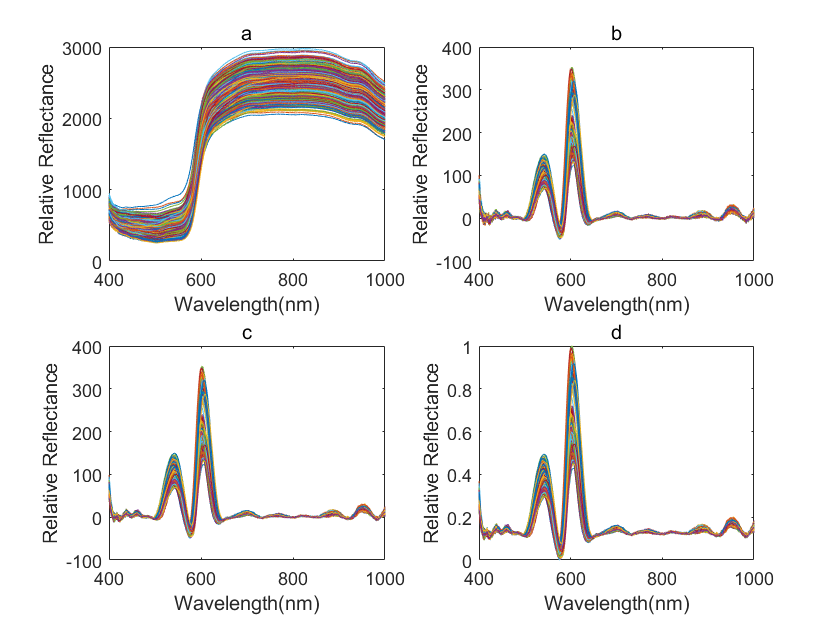

figure;
subplot(2,2,1);
for k = 1:size(X_nir_totaled, 1)
    plot(effwavelengths, X_nir_total(k, :));
    hold on;
end 
xlim([400, 1000])
xlabel('Wavelength(nm)')
ylabel('Relative Reflectance')
title('a')

subplot(2,2,2);
for k = 1:size(X_nir_totaled, 1)
    plot(effwavelengths, X_total_air(k, :));
    hold on;
end 
xlim([400, 1000])
xlabel('Wavelength(nm)')
ylabel('Relative Reflectance')
title('b')

subplot(2,2,3);
for k = 1:size(X_nir_totaled, 1)
    plot(effwavelengths, X_total_air_sg(k, :));
    hold on;
end
xlim([400, 1000])
xlabel('Wavelength(nm)')
ylabel('Relative Reflectance')
title('c')

subplot(2,2,4);
for k = 1:size(X_nir_totaled, 1)
    plot(effwavelengths, X_total_air_sg_01(k, :));
    hold on;
end 
xlim([400, 1000])
xlabel('Wavelength(nm)')
ylabel('Relative Reflectance')
title('d')

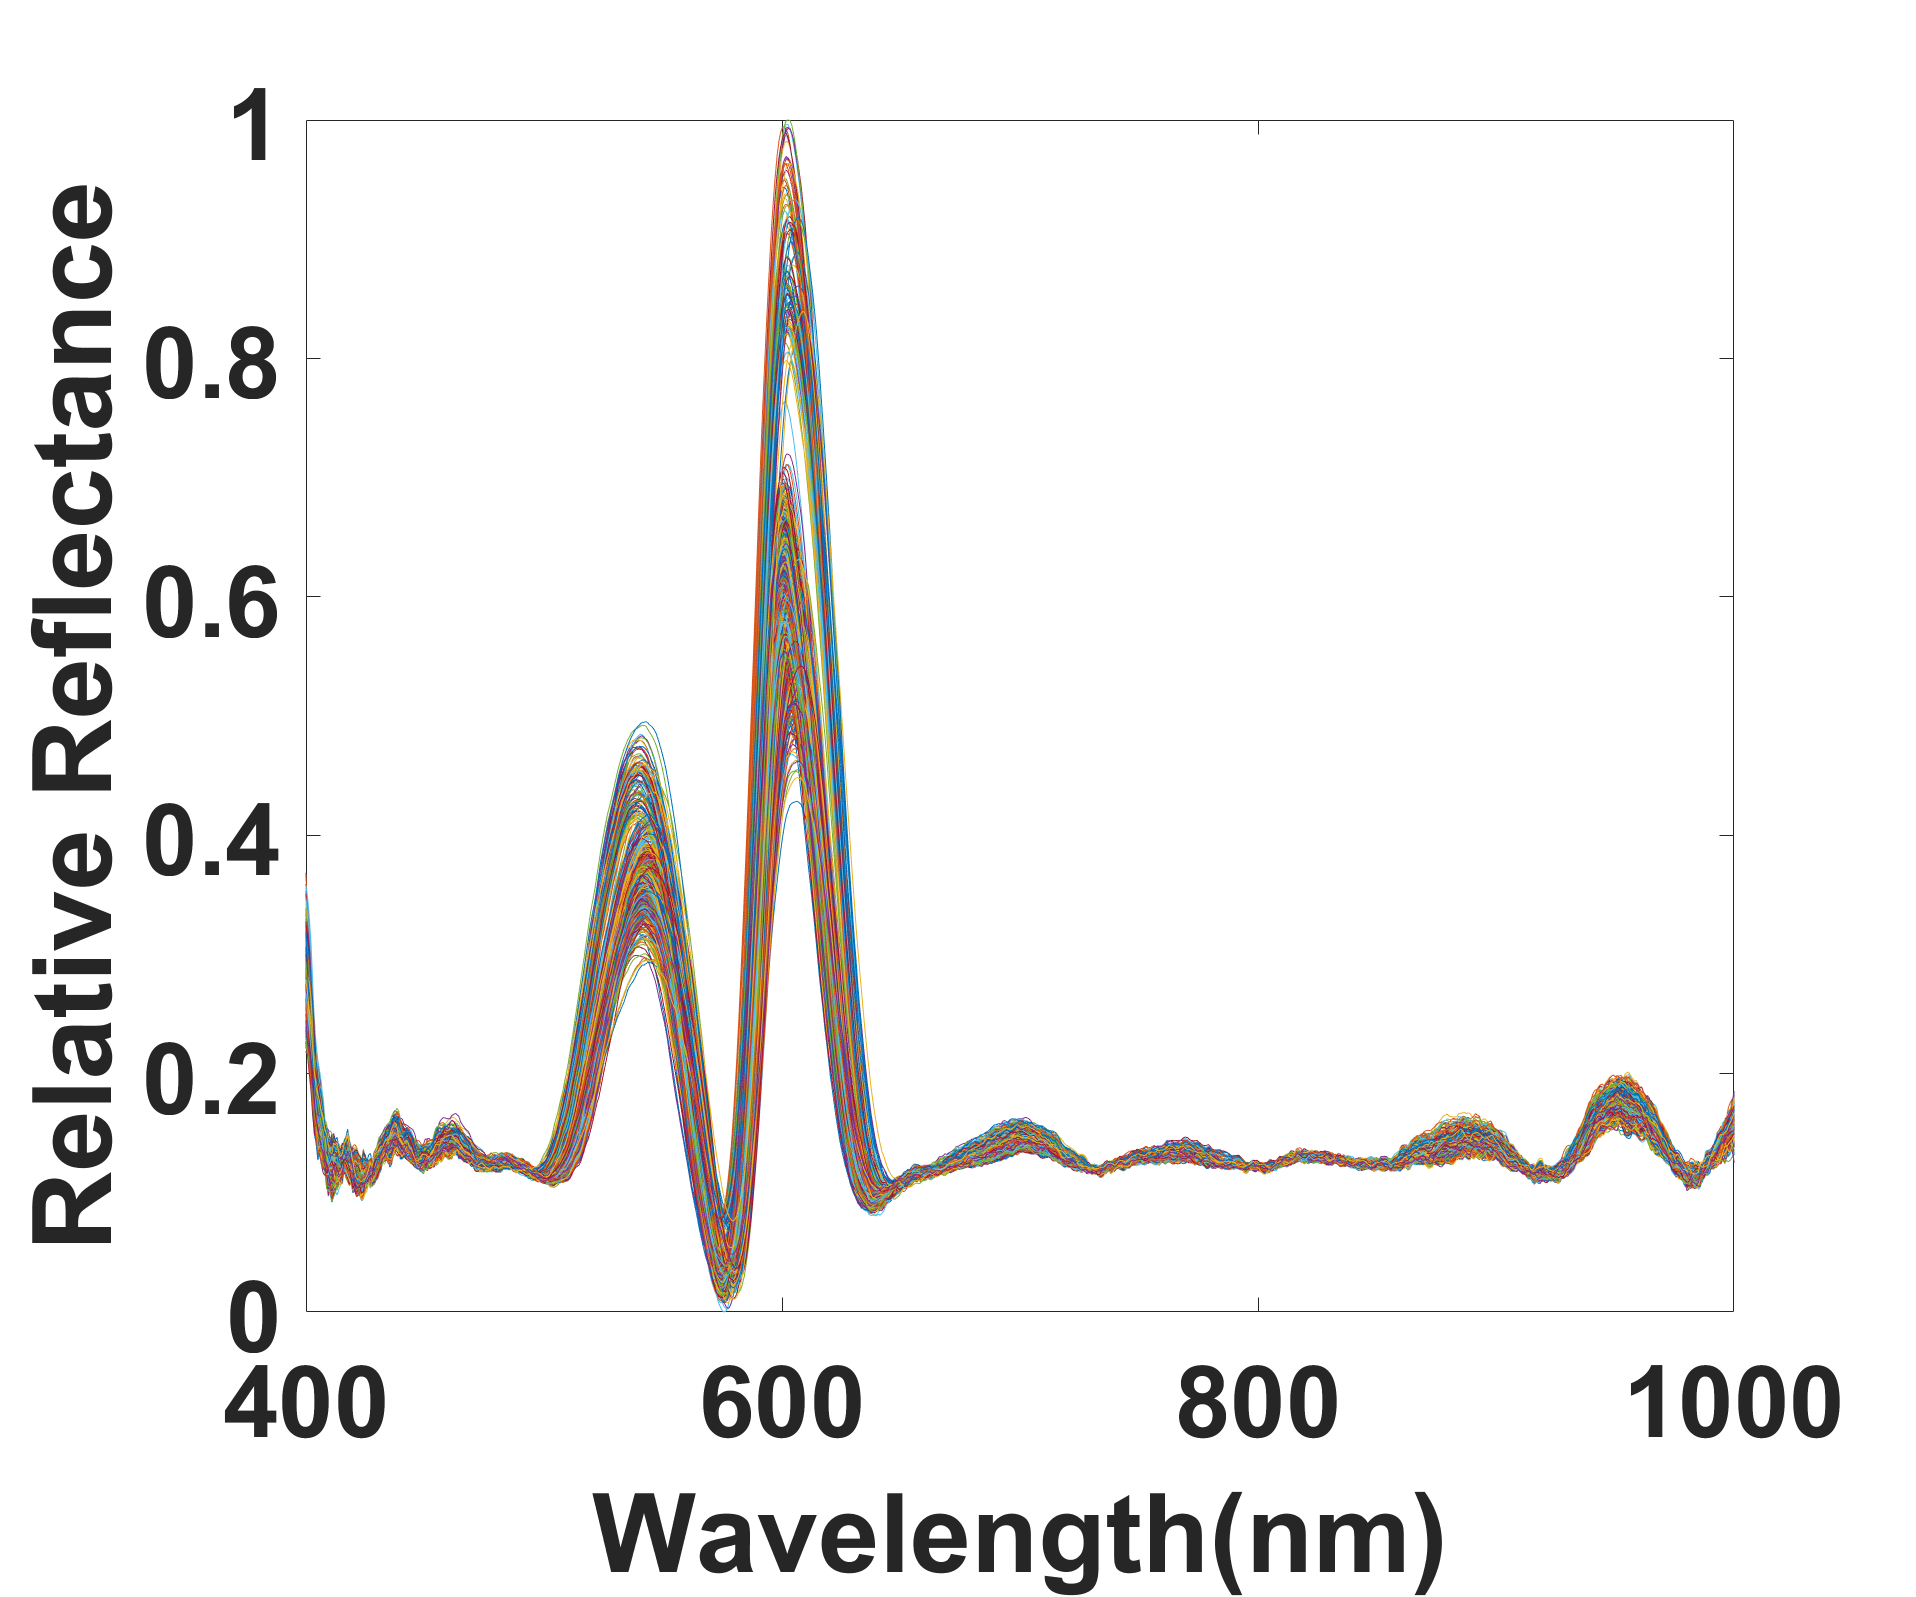

figure('Units','normalized','Position',[0, 0, 0.75, 1]);
for k = 1:size(X_nir_totaled, 1)
    plot(effwavelengths, X_total_air_sg_01(k, :));
    hold on;
end 
xlim([400, 1000])
xlabel('Wavelength(nm)')
ylabel('Relative Reflectance')
set(gca,'fontsize',50, 'FontWeight','bold');